clear all
load fisheriris


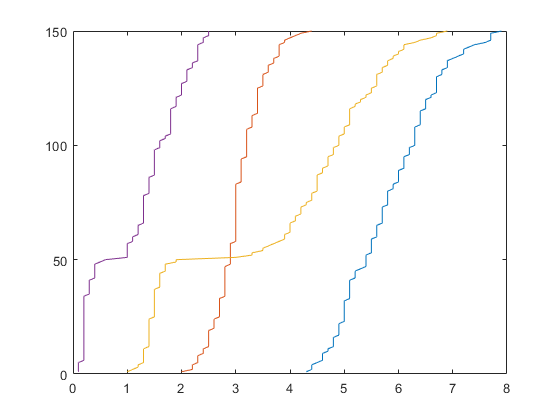

rng('default')
% rand(2,2);
[C,ia,ic] = unique(species);

y = [ic==1 ic==2 ic==3];
indexes= randperm(150);

plot(sort(meas()),(1:150))

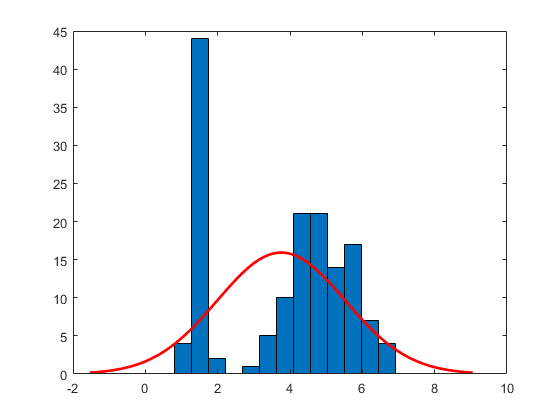

histfit((meas(:,3)))

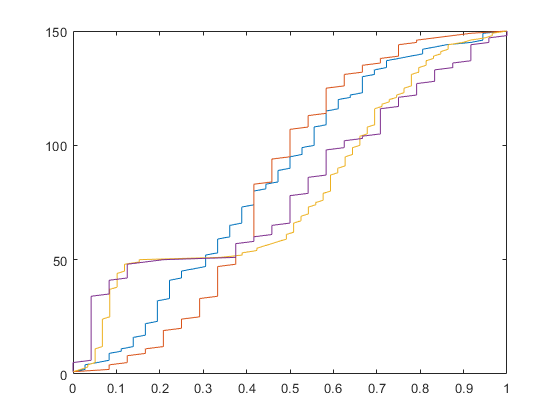


input = normalize(meas(indexes,:),'range');
plot(sort((input)), 1:150)

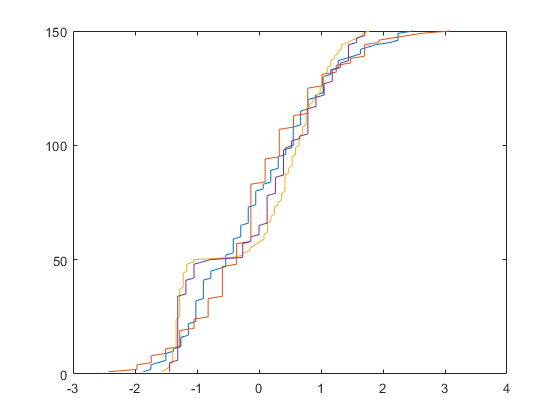


output = y(indexes,:);

input2 = normalize(meas(indexes,:));

g = (1 + exp(-1 * input2)) .^ -1;

plot(sort((input2)), 1:150)

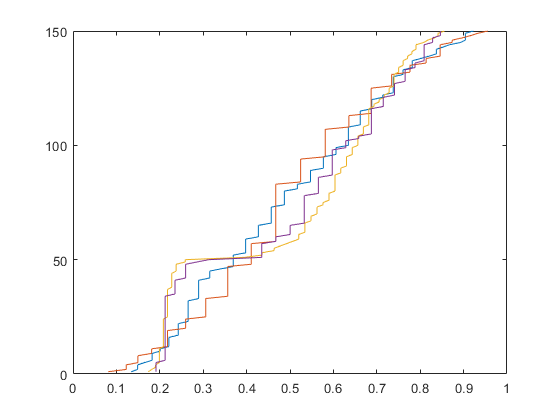

plot(sort((g)), 1:150)


testinput = g((end-49):end,:);
testoutput = output((end-49):end,:);

batchsize = 100;

in = g(1:batchsize,:);
out = output(1:batchsize,:);

n = 1;


knots = 10

knots = 10

M = 0.5*[1 -2 1; -2 2 1; 1 0 0];

N_a=zeros(batchsize,knots+2);
N_b=zeros(batchsize,knots+2);
N_c=zeros(batchsize,knots+2);
N_d=zeros(batchsize,knots+2);

B=[];
C=[];


% Vandermonde ----------

for i = 1:batchsize
    
    index_a(i)= floor((in(i,1)*knots+(10*knots*eps)))+1;
    index_b(i)= floor((in(i,2)*knots+(10*knots*eps)))+1;
    index_c(i)= floor((in(i,3)*knots+(10*knots*eps)))+1;
    index_d(i)= floor((in(i,4)*knots+(10*knots*eps)))+1;
    
    Ntemp_a = (mod(in(i,1),1/knots)*knots).^linspace(2,0,3)*M';
    Ntemp_b = (mod(in(i,2),1/knots)*knots).^linspace(2,0,3)*M';
    Ntemp_c = (mod(in(i,3),1/knots)*knots).^linspace(2,0,3)*M';
    Ntemp_d = (mod(in(i,4),1/knots)*knots).^linspace(2,0,3)*M';
    
    N_a(i,index_a(i):index_a(i)+2) = Ntemp_a;
    N_b(i,index_b(i):index_b(i)+2) = Ntemp_b;
    N_c(i,index_c(i):index_c(i)+2) = Ntemp_c;
    N_d(i,index_d(i):index_d(i)+2) = Ntemp_d;
  
f= outproduct( N_a(i,:), N_b(i,:), N_c(i,:), N_d(i,:));
    
B(i,:)=f(:)';
    
% a=in(i,1).^[0:n];  % a = a/norm(a);
% b=in(i,2).^[0:n];  % b = b/norm(b);
% c=in(i,3).^[0:n];  % c = c/norm(c);
% d=in(i,4).^[0:n];  % d = d/norm(d);
% 
% f= outproduct(a,b,c,d);
% B(i,:)=f(:)';
end
% ----------- ----------


training logistic sigmoid

w = randn([(knots+2)^4 3])/100;

alpha=1;

tic
for i= 1:10
z1 = B*w;

expp = exp(z1-max(z1,[],1));
p1 = expp./sum(expp,2);
sum(p1,2);
% p1 = max(min(p1, 0.95),0.05);
d1 = p1-out;
w = pinv(B)*(z1-alpha*d1);
end
toc

Elapsed time is 0.681032 seconds.


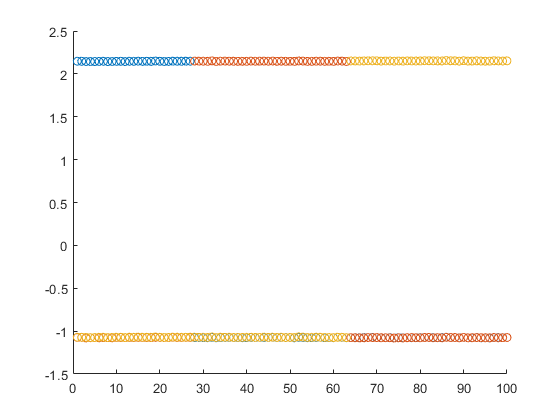


zy = z1; % B*w;
ay = p1;

zet=[];
zet(indexes(1:batchsize),:)=zy(1:end,:);
zet = zet(any(zet,2),:);
scatter(1:batchsize,zet(:,1))
hold on
scatter(1:batchsize,zet(:,2))
scatter(1:batchsize,zet(:,3))
hold off

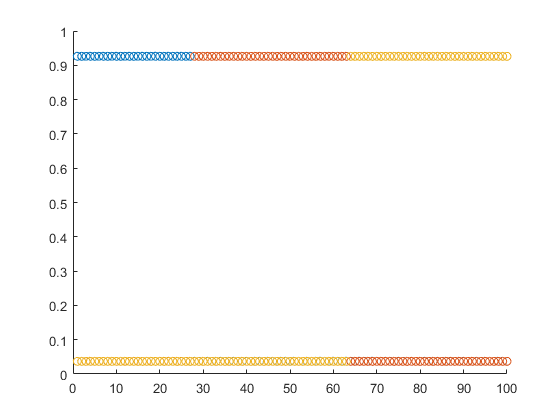


zet=[];
zet(indexes(1:batchsize),:)=ay(1:end,:);
zet = zet(any(zet,2),:);
scatter(1:batchsize,zet(:,1))
hold on
scatter(1:batchsize,zet(:,2))
scatter(1:batchsize,zet(:,3))
hold off

% TEST set


% Vandermonde ----------test
Btest=[];
N_a=zeros(batchsize,knots+2);
N_b=zeros(batchsize,knots+2);
N_c=zeros(batchsize,knots+2);
N_d=zeros(batchsize,knots+2);
for i = 1:50

     testindex_a(i)= floor((testinput(i,1)*knots+(10*knots*eps)))+1;
     testindex_b(i)= floor((testinput(i,2)*knots+(10*knots*eps)))+1;
     testindex_c(i)= floor((testinput(i,3)*knots+(10*knots*eps)))+1;
     testindex_d(i)= floor((testinput(i,4)*knots+(10*knots*eps)))+1;
    
    Ntemp_a = (mod(testinput(i,1),1/knots)*knots).^linspace(2,0,3)*M';
    Ntemp_b = (mod(testinput(i,2),1/knots)*knots).^linspace(2,0,3)*M';
    Ntemp_c = (mod(testinput(i,3),1/knots)*knots).^linspace(2,0,3)*M';
    Ntemp_d = (mod(testinput(i,4),1/knots)*knots).^linspace(2,0,3)*M';
    
    N_a(i,testindex_a(i):testindex_a(i)+2) = Ntemp_a;
    N_b(i,testindex_b(i):testindex_b(i)+2) = Ntemp_b;
    N_c(i,testindex_c(i):testindex_c(i)+2) = Ntemp_c;
    N_d(i,testindex_d(i):testindex_d(i)+2) = Ntemp_d;
  
f= outproduct( N_a(i,:), N_b(i,:), N_c(i,:), N_d(i,:));
    
Btest(i,:)=f(:)';

end



% zytest = Btest*recon(:);

zytest = Btest*w;
exppy = exp(zytest-max(zytest,[],2));
pytest = exppy./sum(exppy,2);

[M, I] = max(pytest,[],2); 

misclassif = ~(I==ic(indexes((end-49):end)));
sum(abs(misclassif))/50

ans = 0.0200

sum(abs(pytest-testoutput), 'all')/(150)

ans = 0.1108


C = confusionmat(I,ic(indexes((end-49):end)))

C =     23     0     0
     0    13     0
     0     1    13


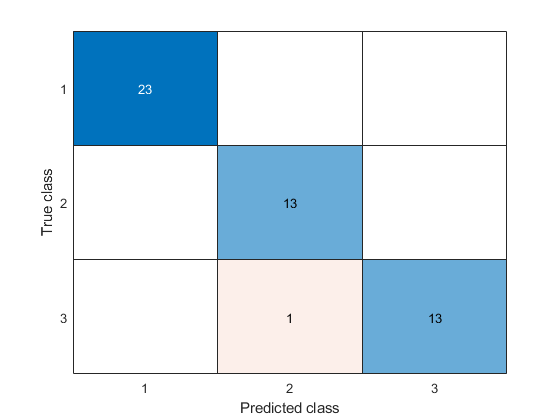

confusionchart(C);

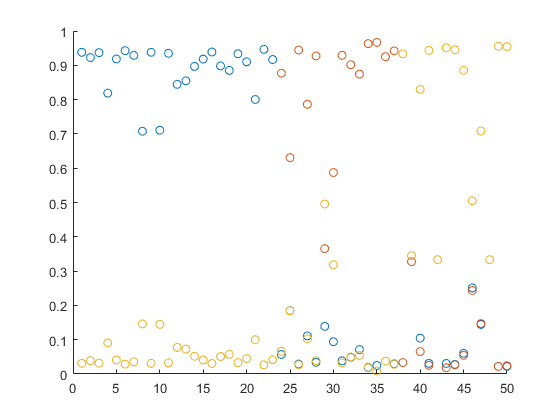


% scatter(1:50,misclassif);

zet=[];
zet(indexes((end-49):end),:)=pytest(1:end,:);
zet = zet(any(zet,2),:);
scatter(1:50,zet(:,1))
hold on
scatter(1:50,zet(:,2))
scatter(1:50,zet(:,3))
hold off



% rataa = norm(y-output)/norm(output)



wplot = reshape(w(:,1),(knots+2)*[1 1 1 1])

wplot = wplot(:,:,1,1) =

   1.0e-14 *

   -0.0111   -0.1892    0.0106   -0.0081    0.0462   -0.0960   -0.0307    0.0028   -0.0123         0         0         0
   -0.0215   -0.0191   -0.0156   -0.0083    0.1631   -0.0101   -0.0049    0.0056    0.0000         0         0         0
    0.2752    0.0337   -0.0125   -0.0178   -0.0074    0.0017    0.0022   -0.0004   -0.0005         0         0         0
   -0.5829    0.0190   -0.0384    0.0012    0.0372   -0.1003   -0.0097    0.0103         0         0         0         0
   -0.5361   -0.0566   -0.0110    0.0148    0.8669   -0.0060    0.0170    0.0138         0         0         0         0
   -0.0514    0.1789   -0.1028    0.0386   -0.0049    0.0157    0.0597    0.0050         0         0         0         0
   -0.0195   -0.5712    0.4416   -0.0242   -0.0040   -0.0016   -0.0205    0.0025         0         0         0         0
   -0.0256   -0.0165   -0.1110   -0.0667   -0.0067   -0.0961    0.2108   -0.0160         0         0         0   


% surf(1:knots+1,1:knots+2,wplot(:,:,1,1))
% surf(input(:,1),input(:,2),double(rehape(y(:,1), []))

xx=in(:,1)

xx =     0.9040
    0.2895
    0.3693
    0.2895
    0.2895
    0.3978
    0.5769
    0.3978
    0.7378
    0.9040


yy=in(:,2)

yy =     0.3565
    0.2178
    0.6870
    0.6870
    0.8137
    0.9322
    0.4672
    0.2594
    0.4672
    0.2594


zz=double((out(:,3)))

zz =      1
     0
     0
     0
     0
     0
     0
     0
     1
     1


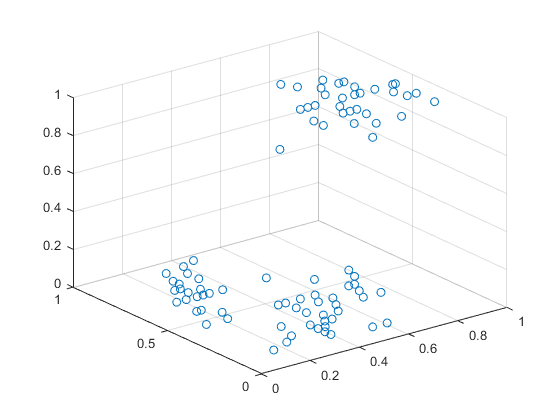

scatter3(xx,yy,zz)


zz=double((output(:,3)))

zz =      1
     0
     0
     0
     0
     0
     0
     0
     1
     1


zz=p1(:,3)

zz =     0.9262
    0.0369
    0.0369
    0.0370
    0.0370
    0.0369
    0.0369
    0.0369
    0.9262
    0.9262


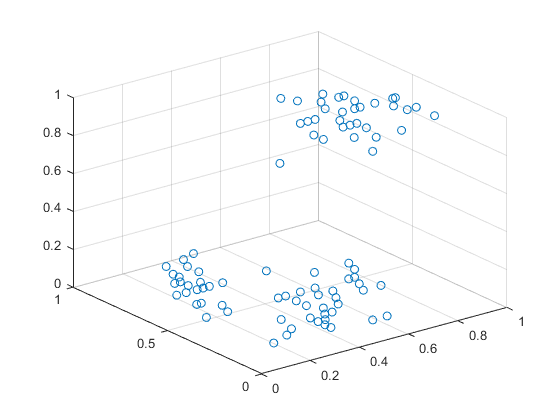


% zz=input(:,3)
% plot3(xx,yy,zz,'.-')
scatter3(xx,yy,zz)

ii=1

ii = 1

for re = logspace(-10,-0.5)
[G, rk] = ttsvd(wplot,re)
suz=0
for k=1:4
    suz = suz + numel(G{k});
end

numberelements = numel(wplot)

numberelements/suz
recon = tcontract(G);


ploto(ii) = sum(abs(recon-wplot),'all')/numberelements

plotosuz(ii)=suz
ii=ii+1;
end

G = 4×1 cell array
    { 1×12×11 double}
    {11×12×44 double}
    {44×12×10 double}
    {10×12    double}


rk =      1
    11
    44
    10


suz = 0

numberelements = 20736

ans = 1.8286

ploto = 5.2422e-08

plotosuz = 11340

G = 4×1 cell array
    { 1×12×11 double}
    {11×12×44 double}
    {44×12×10 double}
    {10×12    double}


rk =      1
    11
    44
    10


suz = 0

numberelements = 20736

ans = 1.8286

ploto = 	1.0e+-7 *

    0.5242    0.5242


plotosuz =        11340       11340


G = 4×1 cell array
    { 1×12×11 double}
    {11×12×44 double}
    {44×12×10 double}
    {10×12    double}


rk =      1
    11
    44
    10


suz = 0

numberelements = 20736

ans = 1.8286

ploto = 	1.0e+-7 *

    0.5242    0.5242    0.5242


plotosuz =        11340       11340       11340


G = 4×1 cell array
    { 1×12×11 double}
    {11×12×44 double}
    {44×12×10 double}
    {10×12    double}


rk =      1
    11
    44
    10


suz = 0

numberelements = 20736

ans = 1.8286

ploto = 	1.0e+-7 *

    0.5242    0.5242    0.5242    0.5242


plotosuz =        11340       11340       11340       11340


G = 4×1 cell array
    { 1×12×11 double}
    {11×12×43 double}
    {43×12×10 double}
    {10×12    double}


rk =      1
    11
    43
    10


suz = 0

numberelements = 20736

ans = 1.8701

ploto = 	1.0e+-6 *

    0.0524    0.0524    0.0524    0.0524    0.2692


plotosuz =        11340       11340       11340       11340       11088


G = 4×1 cell array
    { 1×12×11 double}
    {11×12×43 double}
    {43×12×10 double}
    {10×12    double}


rk =      1
    11
    43
    10


suz = 0

numberelements = 20736

ans = 1.8701

ploto = 	1.0e+-6 *

    0.0524    0.0524    0.0524    0.0524    0.2692    0.2692


plotosuz =        11340       11340       11340       11340       11088       11088


G = 4×1 cell array
    { 1×12×10 double}
    {10×12×44 double}
    {44×12×10 double}
    {10×12    double}


rk =      1
    10
    44
    10


suz = 0

numberelements = 20736

ans = 1.9200

ploto = 	1.0e+-6 *

    0.0524    0.0524    0.0524    0.0524    0.2692    0.2692    0.2688


plotosuz =        11340       11340       11340       11340       11088       11088       10800


G = 4×1 cell array
    { 1×12×10 double}
    {10×12×43 double}
    {43×12×10 double}
    {10×12    double}


rk =      1
    10
    43
    10


suz = 0

numberelements = 20736

ans = 1.9636

ploto = 	1.0e+-6 *

    0.0524    0.0524    0.0524    0.0524    0.2692    0.2692    0.2688    0.4851


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560


G = 4×1 cell array
    { 1×12×10 double}
    {10×12×43 double}
    {43×12×10 double}
    {10×12    double}


rk =      1
    10
    43
    10


suz = 0

numberelements = 20736

ans = 1.9636

ploto = 	1.0e+-6 *

    0.0524    0.0524    0.0524    0.0524    0.2692    0.2692    0.2688    0.4851    0.4851


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560


G = 4×1 cell array
    { 1×12×10 double}
    {10×12×42 double}
    {42×12×10 double}
    {10×12    double}


rk =      1
    10
    42
    10


suz = 0

numberelements = 20736

ans = 2.0093

ploto = 	1.0e+-5 *

    0.0052    0.0052    0.0052    0.0052    0.0269    0.0269    0.0269    0.0485    0.0485    0.1580


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320


G = 4×1 cell array
    { 1×12×10 double}
    {10×12×42 double}
    {42×12×10 double}
    {10×12    double}


rk =      1
    10
    42
    10


suz = 0

numberelements = 20736

ans = 2.0093

ploto = 	1.0e+-5 *

    0.0052    0.0052    0.0052    0.0052    0.0269    0.0269    0.0269    0.0485    0.0485    0.1580    0.1580


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320


G = 4×1 cell array
    { 1×12×10 double}
    {10×12×41 double}
    {41×12×10 double}
    {10×12    double}


rk =      1
    10
    41
    10


suz = 0

numberelements = 20736

ans = 2.0571

ploto = 	1.0e+-5 *

    0.0052    0.0052    0.0052    0.0052    0.0269    0.0269    0.0269    0.0485    0.0485    0.1580    0.1580    0.1774


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080


G = 4×1 cell array
    { 1×12×10 double}
    {10×12×41 double}
    {41×12×10 double}
    {10×12    double}


rk =      1
    10
    41
    10


suz = 0

numberelements = 20736

ans = 2.0571

ploto = 	1.0e+-5 *

    0.0052    0.0052    0.0052    0.0052    0.0269    0.0269    0.0269    0.0485    0.0485    0.1580    0.1580    0.1774    0.1774


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080       10080


G = 4×1 cell array
    { 1×12×10 double}
    {10×12×41 double}
    {41×12×10 double}
    {10×12    double}


rk =      1
    10
    41
    10


suz = 0

numberelements = 20736

ans = 2.0571

ploto = 	1.0e+-5 *

    0.0052    0.0052    0.0052    0.0052    0.0269    0.0269    0.0269    0.0485    0.0485    0.1580    0.1580    0.1774    0.1774    0.1774


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080       10080       10080


G = 4×1 cell array
    { 1×12×10 double}
    {10×12×41 double}
    {41×12×10 double}
    {10×12    double}


rk =      1
    10
    41
    10


suz = 0

numberelements = 20736

ans = 2.0571

ploto = 	1.0e+-5 *

    0.0052    0.0052    0.0052    0.0052    0.0269    0.0269    0.0269    0.0485    0.0485    0.1580    0.1580    0.1774    0.1774    0.1774    0.1774


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080       10080       10080       10080


G = 4×1 cell array
    { 1×12×10 double}
    {10×12×40 double}
    {40×12×10 double}
    {10×12    double}


rk =      1
    10
    40
    10


suz = 0

numberelements = 20736

ans = 2.1073

ploto = 	1.0e+-5 *

    0.0052    0.0052    0.0052    0.0052    0.0269    0.0269    0.0269    0.0485    0.0485    0.1580    0.1580    0.1774    0.1774    0.1774    0.1774    0.5694


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080       10080       10080       10080        9840


G = 4×1 cell array
    { 1×12×10 double}
    {10×12×40 double}
    {40×12×10 double}
    {10×12    double}


rk =      1
    10
    40
    10


suz = 0

numberelements = 20736

ans = 2.1073

ploto =     0.0052    0.0052    0.0052    0.0052    0.0269    0.0269    0.0269    0.0485    0.0485    0.1580    0.1580    0.1774    0.1774    0.1774    0.1774    0.5694    0.5694


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080       10080       10080       10080        9840        9840


G = 4×1 cell array
    { 1×12×10 double}
    {10×12×39 double}
    {39×12×10 double}
    {10×12    double}


rk =      1
    10
    39
    10


suz = 0

numberelements = 20736

ans = 2.1600

ploto =     0.0052    0.0052    0.0052    0.0052    0.0269    0.0269    0.0269    0.0485    0.0485    0.1580    0.1580    0.1774    0.1774    0.1774    0.1774    0.5694    0.5694    0.7938


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080       10080       10080       10080        9840        9840        9600


G = 4×1 cell array
    { 1×12×10 double}
    {10×12×39 double}
    {39×12×10 double}
    {10×12    double}


rk =      1
    10
    39
    10


suz = 0

numberelements = 20736

ans = 2.1600

ploto =     0.0052    0.0052    0.0052    0.0052    0.0269    0.0269    0.0269    0.0485    0.0485    0.1580    0.1580    0.1774    0.1774    0.1774    0.1774    0.5694    0.5694    0.7938    0.7938


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080       10080       10080       10080        9840        9840        9600        9600


G = 4×1 cell array
    { 1×12×10 double}
    {10×12×38 double}
    {38×12×10 double}
    {10×12    double}


rk =      1
    10
    38
    10


suz = 0

numberelements = 20736

ans = 2.2154

ploto =     0.0005    0.0005    0.0005    0.0005    0.0027    0.0027    0.0027    0.0049    0.0049    0.0158    0.0158    0.0177    0.0177    0.0177    0.0177    0.0569    0.0569    0.0794    0.0794    0.1190


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080       10080       10080       10080        9840        9840        9600        9600        9360


G = 4×1 cell array
    { 1×12×10 double}
    {10×12×37 double}
    {37×12×10 double}
    {10×12    double}


rk =      1
    10
    37
    10


suz = 0

numberelements = 20736

ans = 2.2737

ploto =     0.0005    0.0005    0.0005    0.0005    0.0027    0.0027    0.0027    0.0049    0.0049    0.0158    0.0158    0.0177    0.0177    0.0177    0.0177    0.0569    0.0569    0.0794    0.0794    0.1190    0.2094


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080       10080       10080       10080        9840        9840        9600        9600        9360        9120


G = 4×1 cell array
    { 1×12×10 double}
    {10×12×37 double}
    {37×12×10 double}
    {10×12    double}


rk =      1
    10
    37
    10


suz = 0

numberelements = 20736

ans = 2.2737

ploto =     0.0005    0.0005    0.0005    0.0005    0.0027    0.0027    0.0027    0.0049    0.0049    0.0158    0.0158    0.0177    0.0177    0.0177    0.0177    0.0569    0.0569    0.0794    0.0794    0.1190    0.2094    0.2094


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080       10080       10080       10080        9840        9840        9600        9600        9360        9120        9120


G = 4×1 cell array
    { 1×12×10 double}
    {10×12×36 double}
    {36×12×10 double}
    {10×12    double}


rk =      1
    10
    36
    10


suz = 0

numberelements = 20736

ans = 2.3351

ploto =     0.0005    0.0005    0.0005    0.0005    0.0027    0.0027    0.0027    0.0049    0.0049    0.0158    0.0158    0.0177    0.0177    0.0177    0.0177    0.0569    0.0569    0.0794    0.0794    0.1190    0.2094    0.2094    0.2676


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080       10080       10080       10080        9840        9840        9600        9600        9360        9120        9120        8880


G = 4×1 cell array
    { 1×12×10 double}
    {10×12×35 double}
    {35×12×10 double}
    {10×12    double}


rk =      1
    10
    35
    10


suz = 0

numberelements = 20736

ans = 2.4000

ploto =     0.0005    0.0005    0.0005    0.0005    0.0027    0.0027    0.0027    0.0049    0.0049    0.0158    0.0158    0.0177    0.0177    0.0177    0.0177    0.0569    0.0569    0.0794    0.0794    0.1190    0.2094    0.2094    0.2676    0.3313


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080       10080       10080       10080        9840        9840        9600        9600        9360        9120        9120        8880        8640


G = 4×1 cell array
    { 1×12×10 double}
    {10×12×34 double}
    {34×12×10 double}
    {10×12    double}


rk =      1
    10
    34
    10


suz = 0

numberelements = 20736

ans = 2.4686

ploto =     0.0005    0.0005    0.0005    0.0005    0.0027    0.0027    0.0027    0.0049    0.0049    0.0158    0.0158    0.0177    0.0177    0.0177    0.0177    0.0569    0.0569    0.0794    0.0794    0.1190    0.2094    0.2094    0.2676    0.3313    0.4371


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080       10080       10080       10080        9840        9840        9600        9600        9360        9120        9120        8880        8640        8400


G = 4×1 cell array
    { 1×12×10 double}
    {10×12×33 double}
    {33×12×10 double}
    {10×12    double}


rk =      1
    10
    33
    10


suz = 0

numberelements = 20736

ans = 2.5412

ploto =     0.0005    0.0005    0.0005    0.0005    0.0027    0.0027    0.0027    0.0049    0.0049    0.0158    0.0158    0.0177    0.0177    0.0177    0.0177    0.0569    0.0569    0.0794    0.0794    0.1190    0.2094    0.2094    0.2676    0.3313    0.4371    0.5639


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080       10080       10080       10080        9840        9840        9600        9600        9360        9120        9120        8880        8640        8400        8160


G = 4×1 cell array
    { 1×12×10 double}
    {10×12×32 double}
    {32×12×10 double}
    {10×12    double}


rk =      1
    10
    32
    10


suz = 0

numberelements = 20736

ans = 2.6182

ploto =     0.0005    0.0005    0.0005    0.0005    0.0027    0.0027    0.0027    0.0049    0.0049    0.0158    0.0158    0.0177    0.0177    0.0177    0.0177    0.0569    0.0569    0.0794    0.0794    0.1190    0.2094    0.2094    0.2676    0.3313    0.4371    0.5639    0.7747


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080       10080       10080       10080        9840        9840        9600        9600        9360        9120        9120        8880        8640        8400        8160        7920


G = 4×1 cell array
    { 1×12×10 double}
    {10×12×31 double}
    {31×12×10 double}
    {10×12    double}


rk =      1
    10
    31
    10


suz = 0

numberelements = 20736

ans = 2.7000

ploto =     0.0001    0.0001    0.0001    0.0001    0.0003    0.0003    0.0003    0.0005    0.0005    0.0016    0.0016    0.0018    0.0018    0.0018    0.0018    0.0057    0.0057    0.0079    0.0079    0.0119    0.0209    0.0209    0.0268    0.0331    0.0437    0.0564    0.0775    0.1040


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080       10080       10080       10080        9840        9840        9600        9600        9360        9120        9120        8880        8640        8400        8160        7920        7680


G = 4×1 cell array
    { 1×12×10 double}
    {10×12×31 double}
    {31×12×9  double}
    { 9×12    double}


rk =      1
    10
    31
     9


suz = 0

numberelements = 20736

ans = 2.8421

ploto =     0.0001    0.0001    0.0001    0.0001    0.0003    0.0003    0.0003    0.0005    0.0005    0.0016    0.0016    0.0018    0.0018    0.0018    0.0018    0.0057    0.0057    0.0079    0.0079    0.0119    0.0209    0.0209    0.0268    0.0331    0.0437    0.0564    0.0775    0.1040    0.1152


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080       10080       10080       10080        9840        9840        9600        9600        9360        9120        9120        8880        8640        8400        8160        7920        7680        7296


G = 4×1 cell array
    { 1×12×10 double}
    {10×12×30 double}
    {30×12×10 double}
    {10×12    double}


rk =      1
    10
    30
    10


suz = 0

numberelements = 20736

ans = 2.7871

ploto =     0.0001    0.0001    0.0001    0.0001    0.0003    0.0003    0.0003    0.0005    0.0005    0.0016    0.0016    0.0018    0.0018    0.0018    0.0018    0.0057    0.0057    0.0079    0.0079    0.0119    0.0209    0.0209    0.0268    0.0331    0.0437    0.0564    0.0775    0.1040    0.1152    0.1690


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080       10080       10080       10080        9840        9840        9600        9600        9360        9120        9120        8880        8640        8400        8160        7920        7680        7296        7440


G = 4×1 cell array
    { 1×12×10 double}
    {10×12×30 double}
    {30×12×9  double}
    { 9×12    double}


rk =      1
    10
    30
     9


suz = 0

numberelements = 20736

ans = 2.9338

ploto =     0.0001    0.0001    0.0001    0.0001    0.0003    0.0003    0.0003    0.0005    0.0005    0.0016    0.0016    0.0018    0.0018    0.0018    0.0018    0.0057    0.0057    0.0079    0.0079    0.0119    0.0209    0.0209    0.0268    0.0331    0.0437    0.0564    0.0775    0.1040    0.1152    0.1690


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080       10080       10080       10080        9840        9840        9600        9600        9360        9120        9120        8880        8640        8400        8160        7920        7680        7296        7440


G = 4×1 cell array
    { 1×12×10 double}
    {10×12×29 double}
    {29×12×9  double}
    { 9×12    double}


rk =      1
    10
    29
     9


suz = 0

numberelements = 20736

ans = 3.0316

ploto =     0.0001    0.0001    0.0001    0.0001    0.0003    0.0003    0.0003    0.0005    0.0005    0.0016    0.0016    0.0018    0.0018    0.0018    0.0018    0.0057    0.0057    0.0079    0.0079    0.0119    0.0209    0.0209    0.0268    0.0331    0.0437    0.0564    0.0775    0.1040    0.1152    0.1690


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080       10080       10080       10080        9840        9840        9600        9600        9360        9120        9120        8880        8640        8400        8160        7920        7680        7296        7440


G = 4×1 cell array
    { 1×12×10 double}
    {10×12×28 double}
    {28×12×9  double}
    { 9×12    double}


rk =      1
    10
    28
     9


suz = 0

numberelements = 20736

ans = 3.1361

ploto =     0.0001    0.0001    0.0001    0.0001    0.0003    0.0003    0.0003    0.0005    0.0005    0.0016    0.0016    0.0018    0.0018    0.0018    0.0018    0.0057    0.0057    0.0079    0.0079    0.0119    0.0209    0.0209    0.0268    0.0331    0.0437    0.0564    0.0775    0.1040    0.1152    0.1690


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080       10080       10080       10080        9840        9840        9600        9600        9360        9120        9120        8880        8640        8400        8160        7920        7680        7296        7440


G = 4×1 cell array
    { 1×12×10 double}
    {10×12×27 double}
    {27×12×8  double}
    { 8×12    double}


rk =      1
    10
    27
     8


suz = 0

numberelements = 20736

ans = 3.4286

ploto =     0.0001    0.0001    0.0001    0.0001    0.0003    0.0003    0.0003    0.0005    0.0005    0.0016    0.0016    0.0018    0.0018    0.0018    0.0018    0.0057    0.0057    0.0079    0.0079    0.0119    0.0209    0.0209    0.0268    0.0331    0.0437    0.0564    0.0775    0.1040    0.1152    0.1690


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080       10080       10080       10080        9840        9840        9600        9600        9360        9120        9120        8880        8640        8400        8160        7920        7680        7296        7440


G = 4×1 cell array
    { 1×12×10 double}
    {10×12×25 double}
    {25×12×9  double}
    { 9×12    double}


rk =      1
    10
    25
     9


suz = 0

numberelements = 20736

ans = 3.4980

ploto =     0.0001    0.0001    0.0001    0.0001    0.0003    0.0003    0.0003    0.0005    0.0005    0.0016    0.0016    0.0018    0.0018    0.0018    0.0018    0.0057    0.0057    0.0079    0.0079    0.0119    0.0209    0.0209    0.0268    0.0331    0.0437    0.0564    0.0775    0.1040    0.1152    0.1690


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080       10080       10080       10080        9840        9840        9600        9600        9360        9120        9120        8880        8640        8400        8160        7920        7680        7296        7440


G = 4×1 cell array
    { 1×12×10 double}
    {10×12×24 double}
    {24×12×8  double}
    { 8×12    double}


rk =      1
    10
    24
     8


suz = 0

numberelements = 20736

ans = 3.8400

ploto =     0.0001    0.0001    0.0001    0.0001    0.0003    0.0003    0.0003    0.0005    0.0005    0.0016    0.0016    0.0018    0.0018    0.0018    0.0018    0.0057    0.0057    0.0079    0.0079    0.0119    0.0209    0.0209    0.0268    0.0331    0.0437    0.0564    0.0775    0.1040    0.1152    0.1690


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080       10080       10080       10080        9840        9840        9600        9600        9360        9120        9120        8880        8640        8400        8160        7920        7680        7296        7440


G = 4×1 cell array
    { 1×12×10 double}
    {10×12×23 double}
    {23×12×8  double}
    { 8×12    double}


rk =      1
    10
    23
     8


suz = 0

numberelements = 20736

ans = 4

ploto =     0.0001    0.0001    0.0001    0.0001    0.0003    0.0003    0.0003    0.0005    0.0005    0.0016    0.0016    0.0018    0.0018    0.0018    0.0018    0.0057    0.0057    0.0079    0.0079    0.0119    0.0209    0.0209    0.0268    0.0331    0.0437    0.0564    0.0775    0.1040    0.1152    0.1690


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080       10080       10080       10080        9840        9840        9600        9600        9360        9120        9120        8880        8640        8400        8160        7920        7680        7296        7440


G = 4×1 cell array
    { 1×12×10 double}
    {10×12×23 double}
    {23×12×8  double}
    { 8×12    double}


rk =      1
    10
    23
     8


suz = 0

numberelements = 20736

ans = 4

ploto =     0.0001    0.0001    0.0001    0.0001    0.0003    0.0003    0.0003    0.0005    0.0005    0.0016    0.0016    0.0018    0.0018    0.0018    0.0018    0.0057    0.0057    0.0079    0.0079    0.0119    0.0209    0.0209    0.0268    0.0331    0.0437    0.0564    0.0775    0.1040    0.1152    0.1690


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080       10080       10080       10080        9840        9840        9600        9600        9360        9120        9120        8880        8640        8400        8160        7920        7680        7296        7440


G = 4×1 cell array
    { 1×12×10 double}
    {10×12×21 double}
    {21×12×8  double}
    { 8×12    double}


rk =      1
    10
    21
     8


suz = 0

numberelements = 20736

ans = 4.3636

ploto =     0.0001    0.0001    0.0001    0.0001    0.0003    0.0003    0.0003    0.0005    0.0005    0.0016    0.0016    0.0018    0.0018    0.0018    0.0018    0.0057    0.0057    0.0079    0.0079    0.0119    0.0209    0.0209    0.0268    0.0331    0.0437    0.0564    0.0775    0.1040    0.1152    0.1690


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080       10080       10080       10080        9840        9840        9600        9600        9360        9120        9120        8880        8640        8400        8160        7920        7680        7296        7440


G = 4×1 cell array
    { 1×12×9  double}
    { 9×12×23 double}
    {23×12×8  double}
    { 8×12    double}


rk =      1
     9
    23
     8


suz = 0

numberelements = 20736

ans = 4.2353

ploto =     0.0001    0.0001    0.0001    0.0001    0.0003    0.0003    0.0003    0.0005    0.0005    0.0016    0.0016    0.0018    0.0018    0.0018    0.0018    0.0057    0.0057    0.0079    0.0079    0.0119    0.0209    0.0209    0.0268    0.0331    0.0437    0.0564    0.0775    0.1040    0.1152    0.1690


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080       10080       10080       10080        9840        9840        9600        9600        9360        9120        9120        8880        8640        8400        8160        7920        7680        7296        7440


G = 4×1 cell array
    { 1×12×9  double}
    { 9×12×21 double}
    {21×12×8  double}
    { 8×12    double}


rk =      1
     9
    21
     8


suz = 0

numberelements = 20736

ans = 4.6203

ploto =     0.0001    0.0001    0.0001    0.0001    0.0003    0.0003    0.0003    0.0005    0.0005    0.0016    0.0016    0.0018    0.0018    0.0018    0.0018    0.0057    0.0057    0.0079    0.0079    0.0119    0.0209    0.0209    0.0268    0.0331    0.0437    0.0564    0.0775    0.1040    0.1152    0.1690


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080       10080       10080       10080        9840        9840        9600        9600        9360        9120        9120        8880        8640        8400        8160        7920        7680        7296        7440


G = 4×1 cell array
    { 1×12×8  double}
    { 8×12×24 double}
    {24×12×10 double}
    {10×12    double}


rk =      1
     8
    24
    10


suz = 0

numberelements = 20736

ans = 3.8400

ploto =     0.0001    0.0001    0.0001    0.0001    0.0003    0.0003    0.0003    0.0005    0.0005    0.0016    0.0016    0.0018    0.0018    0.0018    0.0018    0.0057    0.0057    0.0079    0.0079    0.0119    0.0209    0.0209    0.0268    0.0331    0.0437    0.0564    0.0775    0.1040    0.1152    0.1690


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080       10080       10080       10080        9840        9840        9600        9600        9360        9120        9120        8880        8640        8400        8160        7920        7680        7296        7440


G = 4×1 cell array
    { 1×12×8  double}
    { 8×12×19 double}
    {19×12×8  double}
    { 8×12    double}


rk =      1
     8
    19
     8


suz = 0

numberelements = 20736

ans = 5.4000

ploto =     0.0001    0.0001    0.0001    0.0001    0.0003    0.0003    0.0003    0.0005    0.0005    0.0016    0.0016    0.0018    0.0018    0.0018    0.0018    0.0057    0.0057    0.0079    0.0079    0.0119    0.0209    0.0209    0.0268    0.0331    0.0437    0.0564    0.0775    0.1040    0.1152    0.1690


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080       10080       10080       10080        9840        9840        9600        9600        9360        9120        9120        8880        8640        8400        8160        7920        7680        7296        7440


G = 4×1 cell array
    { 1×12×8  double}
    { 8×12×17 double}
    {17×12×8  double}
    { 8×12    double}


rk =      1
     8
    17
     8


suz = 0

numberelements = 20736

ans = 6

ploto =     0.0001    0.0001    0.0001    0.0001    0.0003    0.0003    0.0003    0.0005    0.0005    0.0016    0.0016    0.0018    0.0018    0.0018    0.0018    0.0057    0.0057    0.0079    0.0079    0.0119    0.0209    0.0209    0.0268    0.0331    0.0437    0.0564    0.0775    0.1040    0.1152    0.1690


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080       10080       10080       10080        9840        9840        9600        9600        9360        9120        9120        8880        8640        8400        8160        7920        7680        7296        7440


G = 4×1 cell array
    { 1×12×7  double}
    { 7×12×18 double}
    {18×12×8  double}
    { 8×12    double}


rk =      1
     7
    18
     8


suz = 0

numberelements = 20736

ans = 6.0632

ploto =     0.0001    0.0001    0.0001    0.0001    0.0003    0.0003    0.0003    0.0005    0.0005    0.0016    0.0016    0.0018    0.0018    0.0018    0.0018    0.0057    0.0057    0.0079    0.0079    0.0119    0.0209    0.0209    0.0268    0.0331    0.0437    0.0564    0.0775    0.1040    0.1152    0.1690


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080       10080       10080       10080        9840        9840        9600        9600        9360        9120        9120        8880        8640        8400        8160        7920        7680        7296        7440


G = 4×1 cell array
    { 1×12×7  double}
    { 7×12×14 double}
    {14×12×8  double}
    { 8×12    double}


rk =      1
     7
    14
     8


suz = 0

numberelements = 20736

ans = 7.6800

ploto =     0.0001    0.0001    0.0001    0.0001    0.0003    0.0003    0.0003    0.0005    0.0005    0.0016    0.0016    0.0018    0.0018    0.0018    0.0018    0.0057    0.0057    0.0079    0.0079    0.0119    0.0209    0.0209    0.0268    0.0331    0.0437    0.0564    0.0775    0.1040    0.1152    0.1690


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080       10080       10080       10080        9840        9840        9600        9600        9360        9120        9120        8880        8640        8400        8160        7920        7680        7296        7440


G = 4×1 cell array
    { 1×12×6  double}
    { 6×12×16 double}
    {16×12×8  double}
    { 8×12    double}


rk =      1
     6
    16
     8


suz = 0

numberelements = 20736

ans = 7.2605

ploto =     0.0001    0.0001    0.0001    0.0001    0.0003    0.0003    0.0003    0.0005    0.0005    0.0016    0.0016    0.0018    0.0018    0.0018    0.0018    0.0057    0.0057    0.0079    0.0079    0.0119    0.0209    0.0209    0.0268    0.0331    0.0437    0.0564    0.0775    0.1040    0.1152    0.1690


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080       10080       10080       10080        9840        9840        9600        9600        9360        9120        9120        8880        8640        8400        8160        7920        7680        7296        7440


G = 4×1 cell array
    { 1×12×5  double}
    { 5×12×17 double}
    {17×12×8  double}
    { 8×12    double}


rk =      1
     5
    17
     8


suz = 0

numberelements = 20736

ans = 7.3846

ploto =     0.0001    0.0001    0.0001    0.0001    0.0003    0.0003    0.0003    0.0005    0.0005    0.0016    0.0016    0.0018    0.0018    0.0018    0.0018    0.0057    0.0057    0.0079    0.0079    0.0119    0.0209    0.0209    0.0268    0.0331    0.0437    0.0564    0.0775    0.1040    0.1152    0.1690


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080       10080       10080       10080        9840        9840        9600        9600        9360        9120        9120        8880        8640        8400        8160        7920        7680        7296        7440


G = 4×1 cell array
    {1×12×5 double}
    {5×12×9 double}
    {9×12×6 double}
    {6×12   double}


rk =      1
     5
     9
     6


suz = 0

numberelements = 20736

ans = 15.7091

ploto =     0.0001    0.0001    0.0001    0.0001    0.0003    0.0003    0.0003    0.0005    0.0005    0.0016    0.0016    0.0018    0.0018    0.0018    0.0018    0.0057    0.0057    0.0079    0.0079    0.0119    0.0209    0.0209    0.0268    0.0331    0.0437    0.0564    0.0775    0.1040    0.1152    0.1690


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080       10080       10080       10080        9840        9840        9600        9600        9360        9120        9120        8880        8640        8400        8160        7920        7680        7296        7440


G = 4×1 cell array
    { 1×12×3  double}
    { 3×12×15 double}
    {15×12×8  double}
    { 8×12    double}


rk =      1
     3
    15
     8


suz = 0

numberelements = 20736

ans = 9.8182

ploto =     0.0001    0.0001    0.0001    0.0001    0.0003    0.0003    0.0003    0.0005    0.0005    0.0016    0.0016    0.0018    0.0018    0.0018    0.0018    0.0057    0.0057    0.0079    0.0079    0.0119    0.0209    0.0209    0.0268    0.0331    0.0437    0.0564    0.0775    0.1040    0.1152    0.1690


plotosuz =        11340       11340       11340       11340       11088       11088       10800       10560       10560       10320       10320       10080       10080       10080       10080        9840        9840        9600        9600        9360        9120        9120        8880        8640        8400        8160        7920        7680        7296        7440


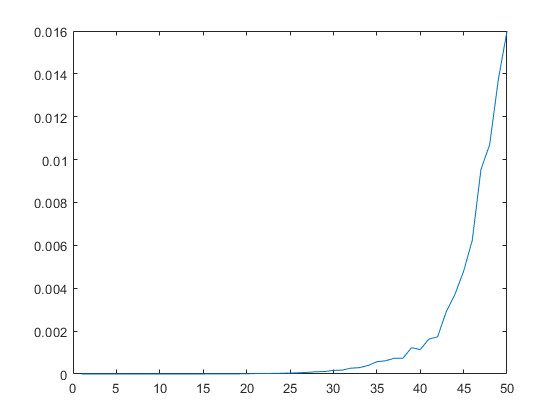


plot(ploto)

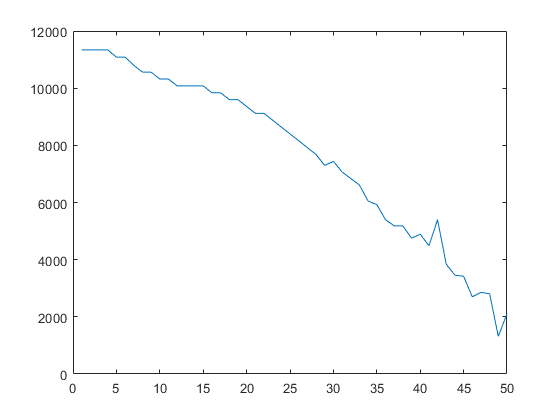

plot(plotosuz)